### Linear regression

First of all lets load our data

addpath('data', 'linearRegression', 'preprocessing', 'Test');

addpath('plotting');

T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');

Error using readtable (line 216)
Unable to open file 'GOOGL_2006-01-01_to_2018-01-01.csv'.

%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');
yr = T{1:end,5};
%y_real = y_real(1000:end);
%X1 = [1:size(y_real,1)]';д
%X1 = [ones(length(X1),1) X1];
%b = X1\y_real;

%X = [X X.^2];
%y = (y.^lamb -1)./lamb;
%y = log(y);
%y = y(2:end) - y(1:end-1);
%std(y)
%y = yr;
% ytr = yr(2:end) - yr(1:end-1);
%y_real = y1;
ytr = yr;

%[y_real, mux, sigmax] = featureNormalize(y_real);
plotData(1:size(yr,1),yr,'День', 'Цена')
hold on

title('Исходный временной ряд')


plotData(1:size(ytr,1),ytr,'День', 'Цена')
hold on
title('Преобразованный код')
hold off

% Scale features and set them to zero mean
%[X, mux, sigmax] = featureNormalize(X);
n_previous_days = 10;
[ynorm, mx_y] = featureNormalizeZeroOne(ytr, max(ytr)*2);
%ynorm = ytr;

%y = y_real;
%Create time series features
[X,ynorm] = timeSeriesFeatures(ynorm,n_previous_days);



%funk splitData(X,y,persentOfTrain, persentOfCv)
%[X_test, m_train, X_cv, m_cv, X_train, y_cv, y_train, m_test, y_test] = splitData(X, ynorm, 0.6, 0.2);
[X_test, m_train, X_cv, m_cv, X_train, y_cv, y_train, m_test, y_test] = splitData(X, ynorm, 0.8, 0.1);

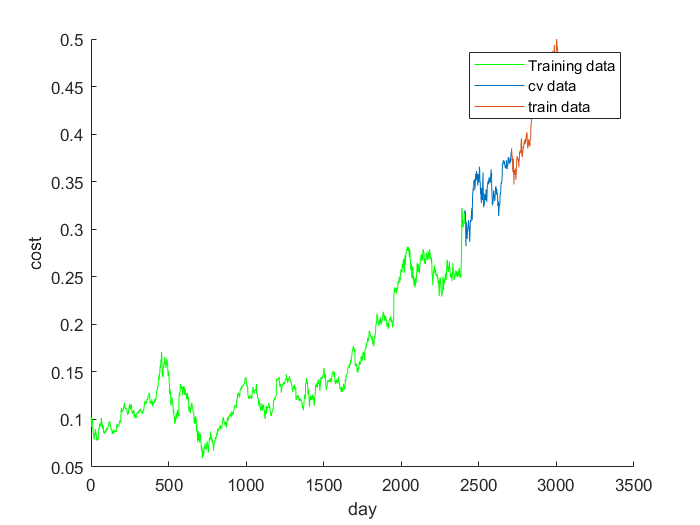

%Plot full data, and split of data
plotData(m_train(1):m_train(2),y_train,'day', 'cost');
hold on;
plot(m_cv(1):m_cv(2),y_cv);
plot(m_test(1):m_test(2),y_test);
legend('Training data', 'cv data', 'train data');
%plot([ones(1:size(y,1)) 1:size(y,1)]'*b, 'yo');
hold off;

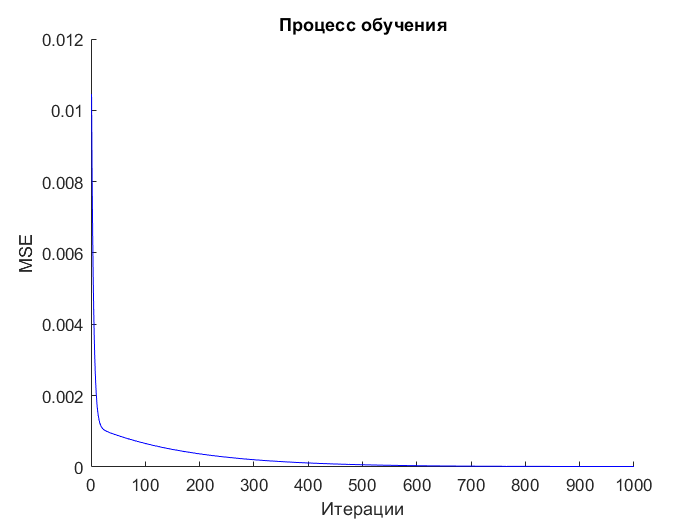

alpha = 0.1;            %0.1 learning rate
iterations = 1000;       %num of iterations500
lambda = 0.5;            %regularisation parameter11 (3.2)

% Init Theta as zeroes with size of X
theta = zeros(size(X,2)+1, 1);
[theta, J_history] = gradientDescentMulti(X_train, y_train, theta, alpha, iterations, lambda);

plotData(1:size(J_history), J_history, 'Итерации','MSE','b');
hold on
title('Процесс обучения')
hold off

fprintf('Cost function = %f', computeCostMulti(X_train,y_train,theta))

Cost function = 0.000014

fprintf('cv cost = %f', computeCostMulti(X_cv,y_cv,theta))

cv cost = 0.000038

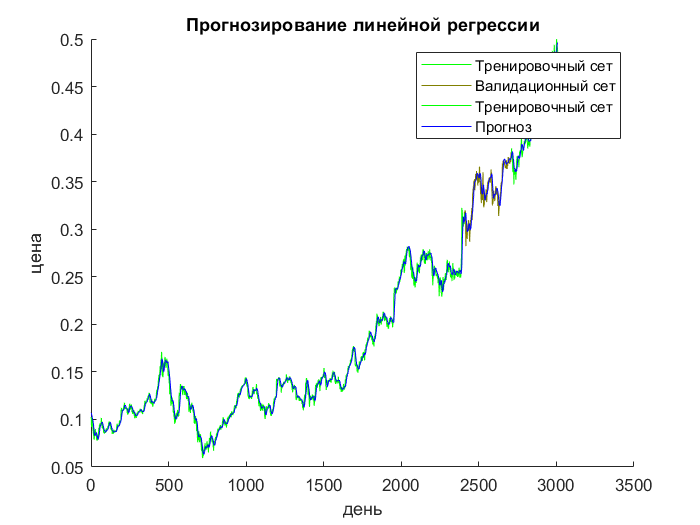


plotData(m_train(1):m_train(2),y_train,'день', 'цена', 'g');
hold on;
plot(m_cv(1):m_cv(2),y_cv,'Color',[0.5,0.5,0]);
plot(m_test(1):m_test(2),y_test, 'Color','g');
hyp = linPredict(X,theta);
plot(hyp,'Color','b');
legend('Тренировочный сет', 'Валидационный сет', 'Тренировочный сет', 'Прогноз');
title('Прогнозирование линейной регрессии');
%plot([ones(1:size(y,1)) 1:size(y,1)]'*b, 'yo');

hold off;

В презентацию

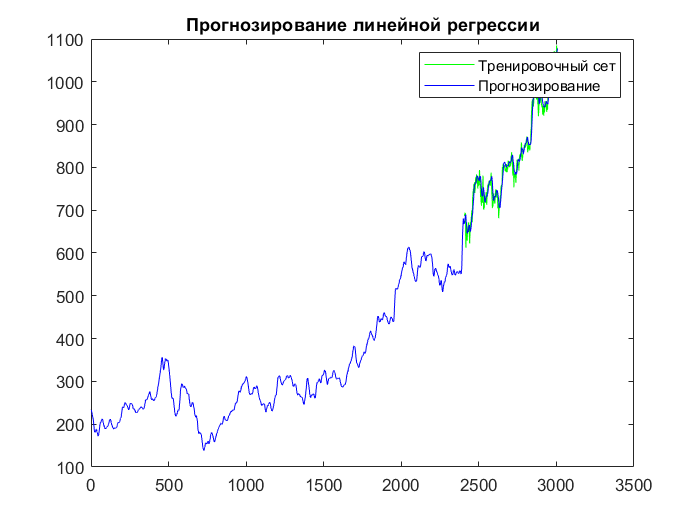



plot(m_cv(1):m_test(2),[y_cv;y_test].*mx_y,'Color','g');
% plot(m_test(1):m_test(2),y_test, 'Color','g');
hold on;
hyp_LR = linPredict(X.*mx_y,theta);
plot(hyp_LR,'Color','b');
legend('Тренировочный сет', 'Прогнозирование');
title('Прогнозирование линейной регрессии');
%plot([ones(1:size(y,1)) 1:size(y,1)]'*b, 'yo');

hold off;

y = y * mx_y;

Undefined function or variable 'y'.

% Plot the linear fit

plotData(1:size(y,1),y,'день', 'цена');
hold on; % keep previous plot visible
%hyp_train = [ones(size(X_train,1), 1) X_train]*theta;
hyp_train = linPredict(X_train, theta);
hyp_train = hyp_train.*mx_y;
plot(m_train(1):m_train(2), hyp_train, '-')

hyp_cv = linPredict(X_cv,theta);
hyp_cv = hyp_cv.*mx_y;
plot(m_cv(1):m_cv(2),hyp_cv, '-');

hyp_test = linPredict(X_test,theta);
hyp_test = hyp_test.*mx_y;
plot(m_test(1):m_test(2),hyp_test, '-');

legend('Исходный ряд', 'Тренировочный сет' , 'Валидационный сет', 'Тестовый сет')
title('Прогноз')
hold off % don't overlay any more plots on this figure
cost = computeCostMulti(X_cv,y_cv,theta)
cost = computeCostMulti(X_test,y_test,theta)
%Mean Absolute Error
y_rtest = y_test*mx_y;
loss = hyp_test - y_rtest;
mean(hyp_test - y_rtest)
mae(loss)
%Mean absolute percentage error
mean(abs(((hyp_test - y_rtest)./y_rtest)'))*100


yr = y.*mx_y;
%plot(m_train(1):m_train(2), hyp-yr(m_train(1):m_train(2)), '-');


plot(m_cv(1):m_cv(2),hyp_cv-yr(m_cv(1):m_cv(2)), '-');
hold on;
title('График остатков')
xlabel = 'День';
ylabel = 'Ошибка предсказания';
plot(m_test(1):m_test(2),hyp_test-yr(m_test(1):m_test(2)), '-');
plot([m_cv(1) m_test(2)],[0 0])
hold off
loss = hyp_test-yr(m_test(1):m_test(2));
fprintf('mean loss = %f', mean(loss));
fprintf('std = %f', std(loss));
hist(loss)

q = predictN(X_test(1,:),theta,500);

'predictN' is not found in the current folder or on the MATLAB path, but exists in:
    D:\als\machine-learning-ex\Diploma

Change the MATLAB current folder or add its folder to the MATLAB path.

plot(m_test(1):(m_test(1)+size(q,1)-1),q, '-');

hold on;
hyp_test = linPredict(X_test,theta);
hyp_test = hyp_test;
plot(m_test(1):m_test(2),hyp_test, '-');
hold off;

_________________________________________________________________

Neural network

addpath('data', 'linearRegression', 'preprocessing');
addpath('plotting');
T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');


y1 = T{1:end,5};
%y1 = y1(2:end) - y1(1:end-1);

options = optimset('MaxIter', 500 );
lambda = 0;     %2
input_layer_size = 10;  %20
hidden_layer_size = 10; %20
num_labels = 1;

n_previous_days = input_layer_size;
[y, mx_y] = featureNormalizeZeroOne(y1, max(y1)*2);
[X,y] = timeSeriesFeatures(y,n_previous_days);
%funk splitData____________________________
% m_train = [round(0*size(X,1))+1, round(0.8*size(X,1))];
% X_train = X(m_train(1):m_train(2),:);
% y_train = y(m_train(1):m_train(2));
% 
% m_cv = [m_train(2)+1, round(0.9*size(X,1))];
% X_cv = X(m_cv(1):m_cv(2),:);
% y_cv = y(m_cv(1):m_cv(2));
% 
% m_test = [m_cv(2)+1, size(X,1)];
% X_test = X(m_test(1):m_test(2),:);
% y_test = y(m_test(1):m_test(2));


[X_test, m_train, X_cv, m_cv, X_train, y_cv, y_train, m_test, y_test] = splitData(X, y, 0.9, 0.05);

%end

costFunction = @(p) nnCostFunction(p, input_layer_size, ...
    hidden_layer_size, num_labels, X_train, y_train, lambda);
[in_nn_params, q, nn_params] = nnTrain(input_layer_size,  hidden_layer_size, num_labels, ...
    X_train, y_train, X_cv, y_cv, costFunction, lambda, 10, options);

Iteration     1 | Cost: 2.099779e-02
Iteration     2 | Cost: 9.129213e-03
Iteration     3 | Cost: 7.019324e-03
Iteration     4 | Cost: 6.786895e-03
Iteration     5 | Cost: 6.664002e-03
Iteration     6 | Cost: 1.340894e-03
Iteration     7 | Cost: 6.131161e-04
Iteration     8 | Cost: 2.627976e-04
Iteration     9 | Cost: 1.748480e-04
Iteration    10 | Cost: 1.710072e-04
Iteration    11 | Cost: 1.622081e-04
Iteration    12 | Cost: 1.599094e-04
Iteration    13 | Cost: 1.597938e-04
Iteration    14 | Cost: 1.597233e-04
Iteration    15 | Cost: 1.459165e-04
Iteration    16 | Cost: 1.332225e-04
Iteration    17 | Cost: 7.632937e-05
Iteration    18 | Cost: 5.784329e-05
Iteration    19 | Cost: 5.079049e-05
Iteration    20 | Cost: 4.829153e-05
Iteration    21 | Cost: 4.369837e-05
Iteration    23 | Cost: 4.356129e-05
Iteration     1 | Cost: 1.680167e-02
Iteration     2 | Cost: 6.963621e-03
Iteration     3 | Cost: 6.825342e-03
Iteration     4 | Cost: 6.526907e-03
Iteration     5 | Cost: 2.291448e-03
I

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));
             
h1 = sigmoid([ones(size(X_train,1), 1) X_train] * Theta1');
hyp_train = sigmoid([ones(size(h1,1),1) h1] * Theta2');
                 
h1 = sigmoid([ones(size(X_cv,1), 1) X_cv] * Theta1');
hyp_cv = sigmoid([ones(size(h1,1),1) h1] * Theta2');

                 
h1 = sigmoid([ones(size(X_test,1), 1) X_test] * Theta1');
hyp_test = sigmoid([ones(size(h1,1),1) h1] * Theta2');


mean(abs(hyp_cv*mx_y - y_cv*mx_y))

ans = 15.3341

mean(abs(((hyp_test*mx_y - y_test*mx_y)./(y_test*mx_y))'))*100

ans = 3.0422

% Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
%                  hidden_layer_size, (input_layer_size + 1));
% 
% Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
%                  num_labels, (hidden_layer_size + 1));


% q = [y_train, hip_train, y_train - hip_train];


% h1 = sigmoid([ones(size(X_test,1), 1) X_test] * Theta1');
% hip_test = sigmoid([ones(size(h1,1),1) h1] * Theta2');

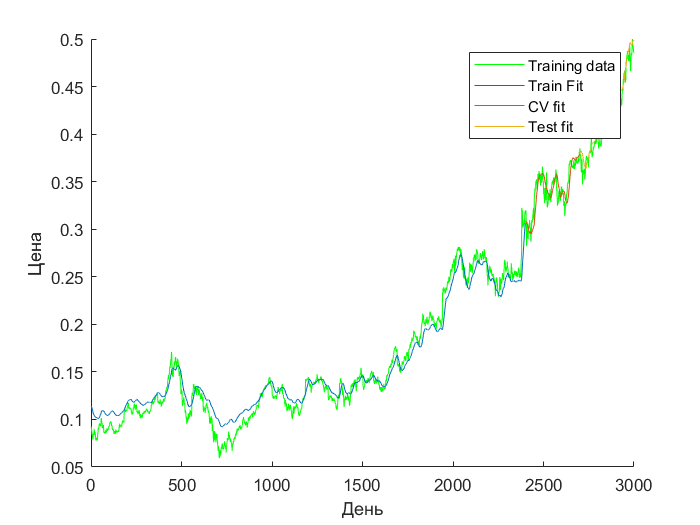

% Plot the nn fit
%yr = y *mx_y;
%h_train_r = hyp

plotData(1:size(y,1),y,'День', 'Цена');
hold on; % keep previous plot visible
plot(m_train(1):m_train(2), hyp_train, '-')

plot(m_cv(1):m_cv(2),hyp_cv, '-');

plot(m_test(1):m_test(2),hyp_test, '-');

legend('Training data', 'Train Fit' , 'CV fit', 'Test fit')
hold off % don't overlay any more plots on this figure

nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X_test, y_test, lambda)

ans = 1.6112e-04

mean(abs(hyp_test*mx_y - y_test*mx_y))

ans = 21.5781

%Mean absolute percentage error
mean(abs(((hyp_test - y_test)./y_test)'))*100

ans = 2.3690


[hyp_test*mx_y, y_test*mx_y, (hyp_test-y_test).*mx_y]

ans = 	1.0e+03 *

    0.8230    0.8241   -0.0010
    0.8236    0.8357   -0.0122
    0.8255    0.8285   -0.0030
    0.8265    0.8221    0.0044
    0.8272    0.8174    0.0099
    0.8280    0.8196    0.0085
    0.8289    0.8099    0.0190
    0.8293    0.8055    0.0239
    0.8294    0.7884    0.0410
    0.8286    0.7822    0.0464


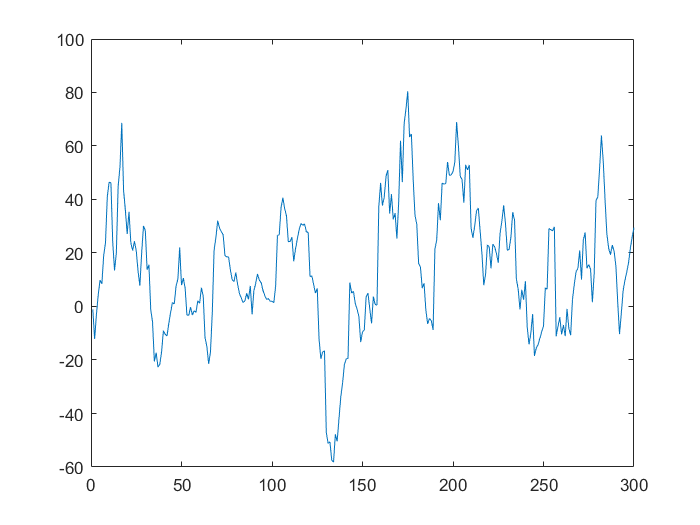

loss = (hyp_test-y_test).*mx_y;
plot(loss)

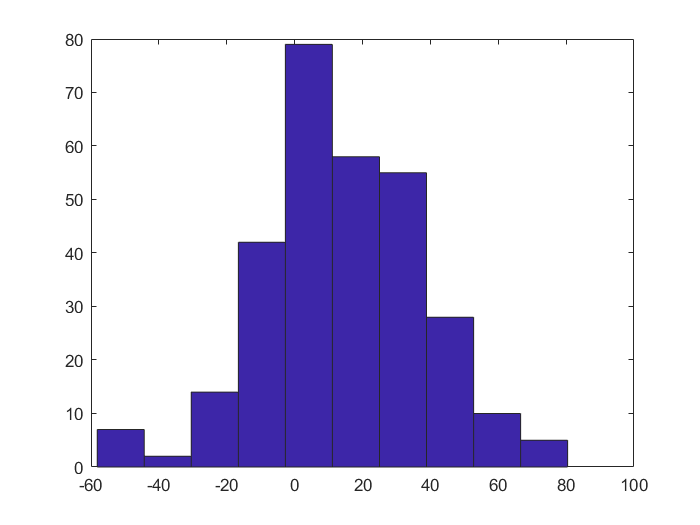

hist(loss)

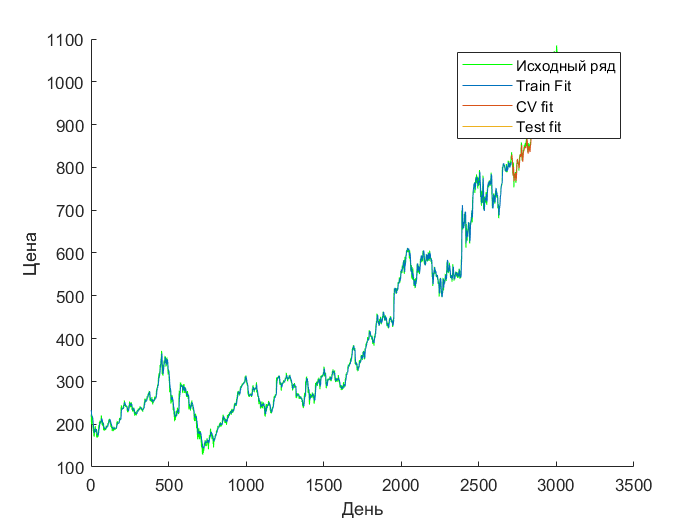

% Plot the nn fit in real values
%yr = y *

plotData(1:size(y,1),y*mx_y,'День', 'Цена');
hold on; % keep previous plot visible
plot(m_train(1):m_train(2), hyp_train*mx_y, '-')

plot(m_cv(1):m_cv(2),hyp_cv*mx_y, '-');

plot(m_test(1):m_test(2),hyp_test*mx_y, '-');

legend('Исходный ряд', 'Train Fit' , 'CV fit', 'Test fit')
hold off % don't overlay any more plots on this figure

Для презентации

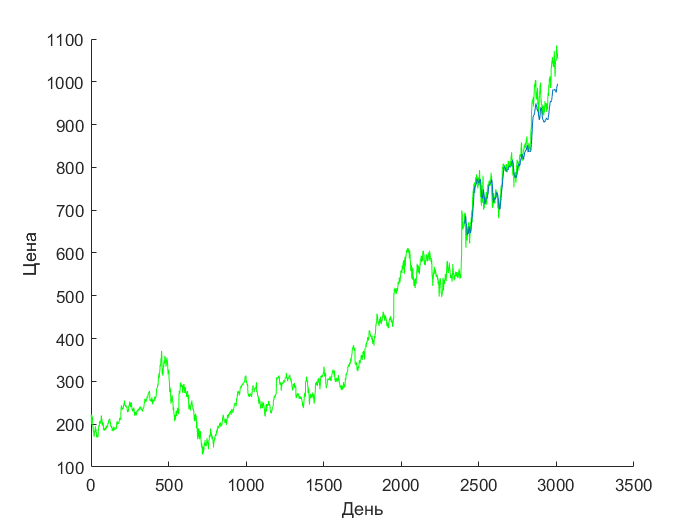

plotData(1:size(y,1),y*mx_y,'День', 'Цена');
hold on; % keep previous plot visible
q = [hyp_cv*mx_y ; hyp_test*mx_y];
plot(m_cv(1):m_test(2), q);

% plot(m_train(1):m_train(2), hyp_train*mx_y, '-')
% 
% plot(m_cv(1):m_cv(2),hyp_cv*mx_y, '-');
% 
% plot(m_test(1):m_test(2),hyp_test*mx_y, '-');

legend('Исходный ряд', 'Предсказания')
hold off % don't overlay any more plots on this figure

q =nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X_test, y_test, lambda)

LSTM

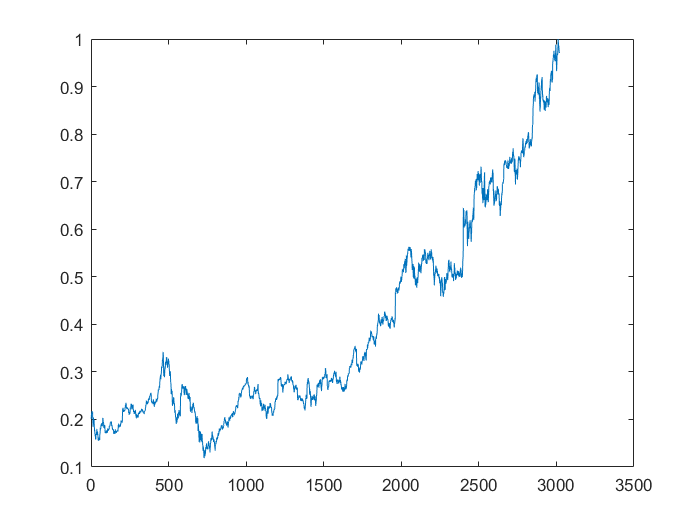

addpath('data', 'FFNN', 'linearRegression', 'plotting', 'preprocessing', 'Test');

T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
yr = T{1:end,5};
%y1 = yr(2000:end);
% y = yr;
%n_previous_days = 10;
%y = log(y1);

%ytr = yr(2:end) - yr(1:end-1);

%[y, mu, sigma] = featureNormalize(ytr);

%y1 = yr;
[y, mx_y] = featureNormalizeZeroOne(yr);

plot(y);

%[y, mx_y] = featureNormalizeZeroOne(y1);
%y = y1;
%[y, mu, sigma] = featureNormalize(y1)
%y = y1;
%[X,y] = timeSeriesFeatures(y,n_previous_days);


m_train = [1, floor(0.8*size(y,1))];
y_train = y(1:m_train(2));

m_test = [m_train(2)+1, size(y,1)];
y_test = y(m_test(1):m_test(2));


XTrain = [y_train(1:end-1)];
YTrain = [y_train(2:end)];

 XTest = y_test(1:end-1);
 YTest = y_test(2:end);


numFeatures = 1;
numHiddenUnits = 10;
numResponses = 1;

maxEpochs = 20;     %16 для 80 10 10 
miniBatchSize = 36; %36 для 80 10 10

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numResponses)
    regressionLayer];

  options = trainingOptions('adam', ...
      'ExecutionEnvironment','cpu', ...
      'MaxEpochs',maxEpochs, ...
      'MiniBatchSize',miniBatchSize, ...
      'GradientThreshold',1, ...
      'Plots','training-progress', ...
      'Verbose',false, ...
      'L2Regularization',0.00006);

% options = trainingOptions('adam', ...
%     'MaxEpochs',250, ...
%     'GradientThreshold',1, ...
%     'InitialLearnRate',0.005, ...
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropPeriod',125, ...
%     'LearnRateDropFactor',0.2, ...
%     'Verbose',0, ...
%     'Plots','training-progress');

% options = trainingOptions('adam', ...
%     'MaxEpochs',250, ...
%     'GradientThreshold',1, ...
%     'InitialLearnRate',0.005, ...
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropPeriod',125, ...
%     'LearnRateDropFactor',0.2, ...
%     'Verbose',0, ...
%     'Plots','training-progress');

%      ...
%data = 
%X_train = [y{:}];
%y = X_t(2:end);
%X_train = X_train(1:end-1);
%net = trainNetwork(num2cell(y_train),y_train,layers,options);
net = trainNetwork(num2cell(XTrain) , YTrain,layers,options);


h_test = net.predict(num2cell(XTest));

Error using parallel.gpu.CUDADevice.hBuild
An unexpected error occurred trying to retrieve CUDA device properties. The CUDA error was:
CUDA_ERROR_UNKNOWN

Error in parallel.gpu.GPUDevice.getDevice (line 76)
            d = parallel.gpu.CUDADevice.hBuild( idx );

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('parallel.gpu.GPUDevice.isAvailable', 'C:\Program Files\MATLAB\R2018b\toolbox\distcomp\gpu\+parallel\+gpu\@GPUDevice\GPUDevice.m', 146)" style="font-weigh

plot(m_test(1):m_test(2), h_test, 'Color', 'b');
hold on;

xlabel = 'День';
ylabel = 'Цена';
plot(m_test(1):m_test(2), y1(m_test(1):m_test(2)), 'Color', 'g')
legend('Предсказания', 'Исходный ряд');
hold off


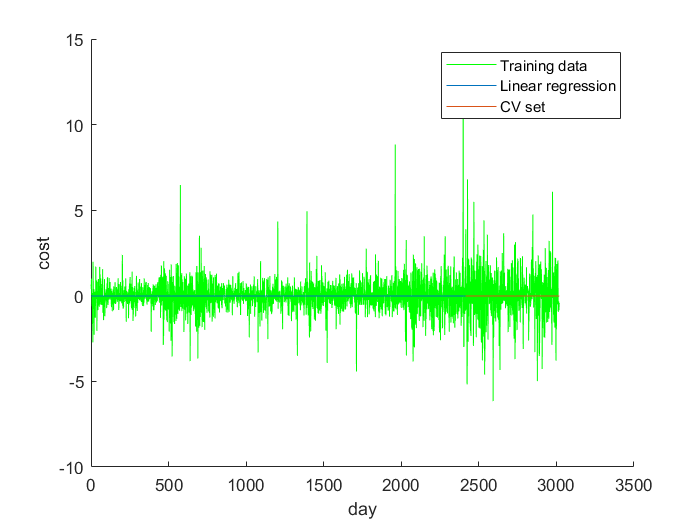

% Plot the nn fit
plotData(1:size(y,1),y,'day', 'cost');
hold on; % keep previous plot visible
plot(m_train(1):m_train(2), net.predict(num2cell(y_train)), '-')

% plot(m_cv(1):m_cv(2),net.predict(num2cell(y_cv)), '-');

plot(m_test(1):m_test(2),net.predict(num2cell(y_test)), '-');

legend('Training data', 'Linear regression' , 'CV set')
hold off % don't overlay any more plots on this figure

%MAPE
hyp_test = net.predict(num2cell(y_test));
hyp_test_norm = hyp_test * mx_y;

y_test_norm = y_test * mx_y;
%MAE
mean(abs(y_test_norm - hyp_test_norm))

ans = single
15.1641


%MAPE
mean(abs(((hyp_test_norm - y_test_norm)./y_test_norm)'))*100

ans = single
1.8188

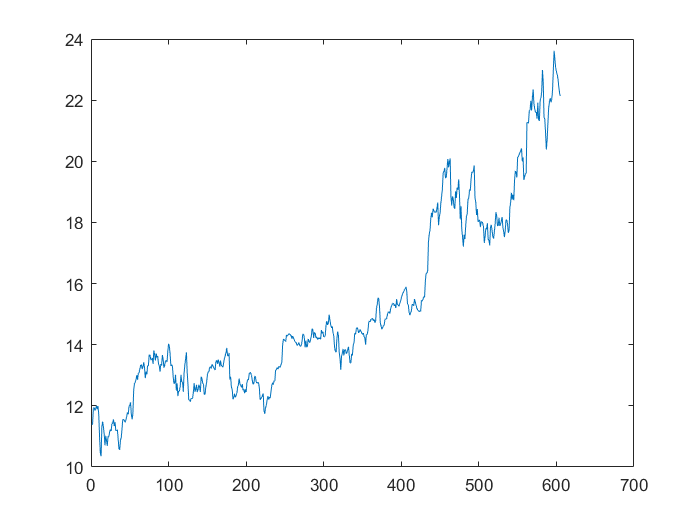

loss = y_test_norm - hyp_test_norm;
plot(loss)

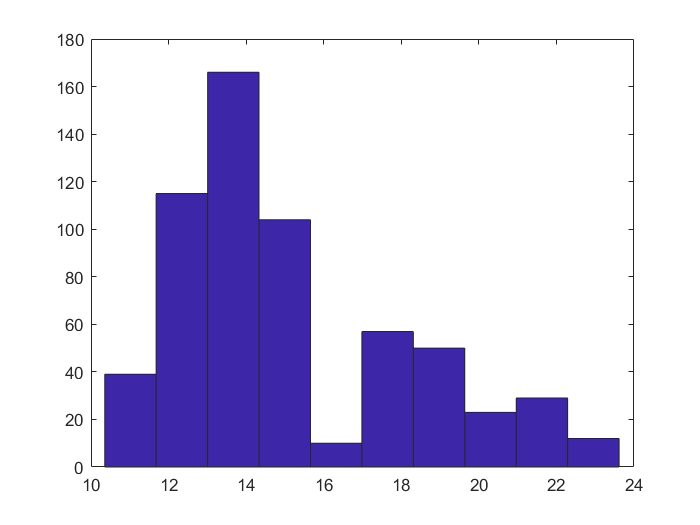

hist(loss)

yy = y_test(10);
xx = [];
for i = 1:100
    x1 = net.predict(num2cell(yy(end)));
    yy = [yy; x1];
end

[yy y_test(10:110) yy - y_test(10:110)]

ans = 101×3 single matrix
    0.7423    0.7423    0.0000
    0.7377    0.7266    0.0111
    0.7329    0.7209    0.0120
    0.7279    0.7198    0.0081
    0.7229    0.7391   -0.0163
    0.7176    0.7483   -0.0307
    0.7122    0.7424   -0.0302
    0.7067    0.7191   -0.0124
    0.7010    0.7112   -0.0102
    0.6951    0.6942    0.0010


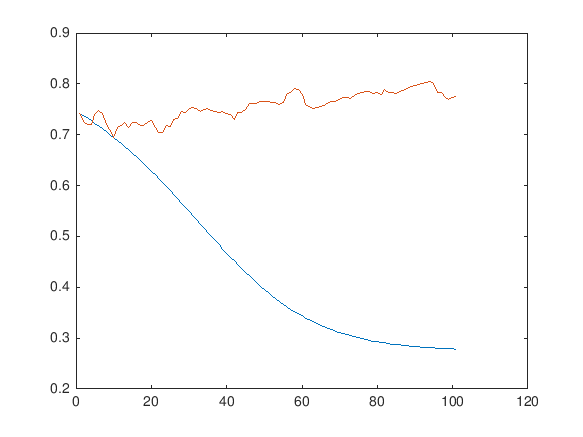

plot(yy)
hold on
plot(y_test(10:110));
hold off


x1 = net.predict(num2cell(y_test(1)));
x2 = net.predict(num2cell(y_test(2)));
x3 = net.predict(num2cell(y_test(3)));

[[x1;x2;x3] y_test(2:4)]

ans = 3×2 single matrix
    0.0537   -0.0558
   -0.0541    0.0248
    0.0227    0.1194


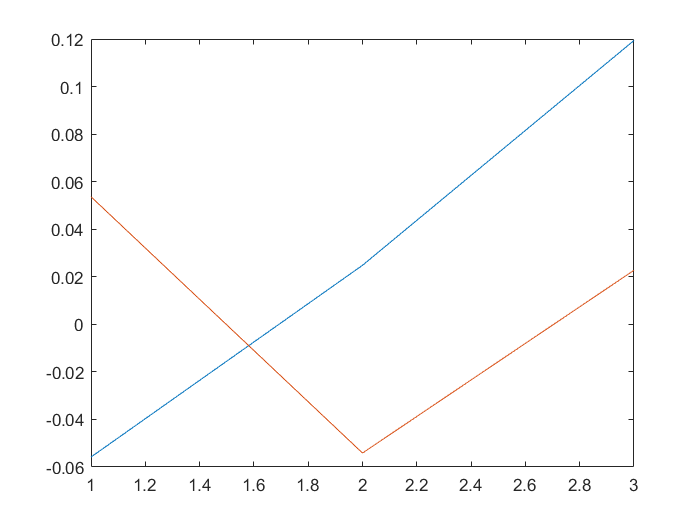

plot(y_test(2:4))
hold on
plot([x1;x2;x3]);
hold off

% qq = zeros(size(loss));
% qq(1) = loss(1);
% for i = 2:size(loss)
%     qq(i) = qq(i-1) + loss(i);
% end
% plot(qq);
plot(m_test(1):m_test(2), qq)

Undefined function or variable 'qq'.

hold on;
plot(yr)
hold off;

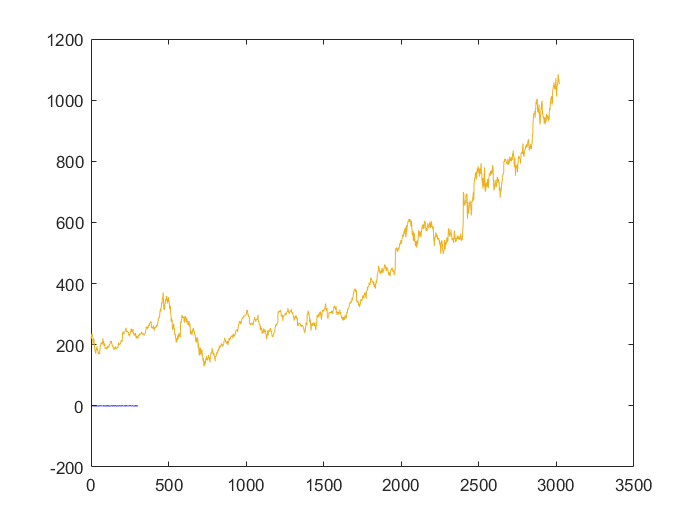

h_test = net.predict(num2cell(y_test));

plot(y_test);
hold on
plot(h_test,'Color', 'b');
hold off

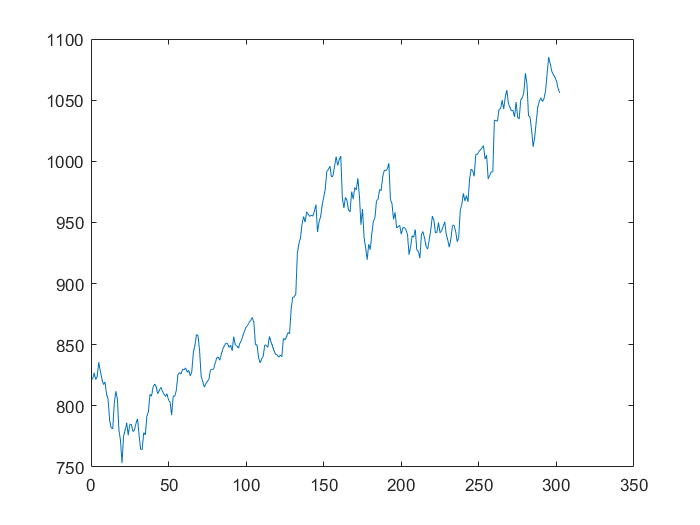

yr_test = (yr(m_test(1):m_test(2)));
plot(yr_test)

q = h_test*mx_y;
qq = yr_test(1,1)

qq = 821.4900

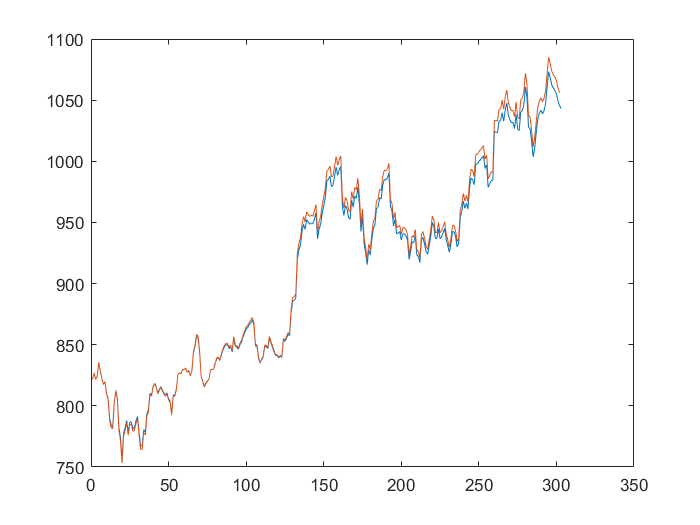


%qq = [qq; qq(end,1) + q(i)]
 for i = 1:size(q,1)
     qq = [qq; qq(end,1) + q(i)];
 end

plot(qq);
hold on
plot(yr_test)
hold off

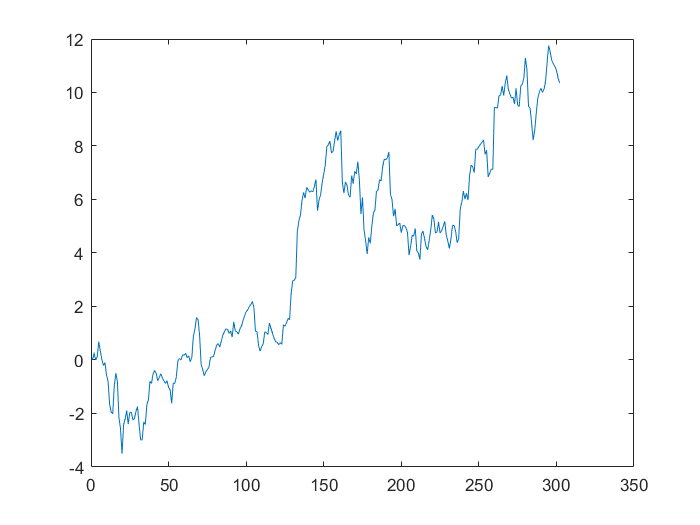

losstest = yr_test - qq(1:end-1);
plot(losstest)

q = net.predict(num2cell(y_train(1)))

q = single
0.2040

y_train(2)

ans = 0.2054

q2 = net.predict(num2cell([y_train(1:10)]))

q2 = 10×1 single column vector
    0.2040
    0.2083
    0.2110
    0.2173
    0.2178
    0.2190
    0.2199
    0.2164
    0.2175
    0.2179


y_train(2:11)

ans =     0.2054
    0.2081
    0.2148
    0.2154
    0.2167
    0.2175
    0.2139
    0.2151
    0.2155
    0.2052


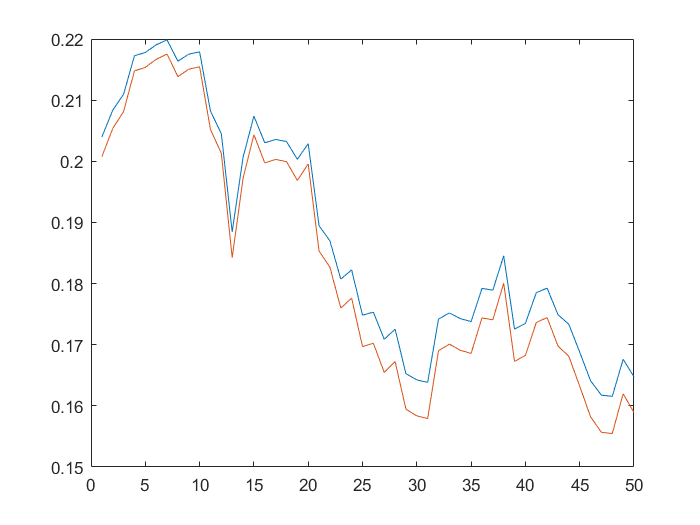

plot(net.predict(num2cell([y_train(1:50)])))
hold on
plot(y_train(1:50))
hold off

Error using num2cell (line 30)
Not enough input arguments.